% Package orientation: Runnable validation or benchmark wrapper. It loads saved models or constructs small checks, then reports metrics/diagnostics without changing training code.

% TEST_GPU_implementation_regression_yacht.mlx
% Load a saved trained network and evaluate held-out yacht regression performance.
% This script does not train. Run a CPU or GPU training script first, then choose which saved backend to load below.

clear; clc;
repo_root = project_root();
addpath(fullfile(repo_root, 'shared', 'matlab'), '-begin');
add_project_paths(repo_root);

%% ---------------- Saved Network ----------------
% This file is created by the matching train script. It stores the training options
% and the best trained bias vector. The test action reconstructs deterministic
% weights from saved options, restores best.B, and evaluates the held-out split.
test_seeds = [1 2 3]; % Independently trained initialization seeds used for release test statistics.
diagnostic_seed_index = 1; % Spike diagnostics use one representative seed to keep live plots readable.
test_backend = 'gpu'; % This script evaluates with the GPU implementation.
trained_model_backend = 'auto'; % 'auto' prefers same-backend trained models, then falls back to the other backend.
[model_files, model_file, trained_model_backend] = snn_resolve_seed_model_files(repo_root, 'regression_yacht', test_backend, test_seeds, diagnostic_seed_index, trained_model_backend);
save_diagnostic_files = false;  % set true to write diagnostic artifacts as well as displaying inline
diag_dir = fullfile(repo_root, 'outputs', 'diagnostics', sprintf('regression_yacht_trained_%s_test_gpu_primary', trained_model_backend));
if save_diagnostic_files && exist(diag_dir, 'dir') ~= 7, mkdir(diag_dir); end
missing_model_files = model_files(cellfun(@(f) exist(f, 'file') ~= 2, model_files));
if ~isempty(missing_model_files)
    error('Saved model(s) not found. Run the matching training script for all requested seeds first. First missing file: %s', missing_model_files{1});
end

%% ---------------- Evaluation Overrides ----------------
% model_file is required. batch_size can be lowered if GPU memory is limited.
% Other fields placed in opts override the saved training options for evaluation only.
opts = struct();
opts.model_files = model_files;
opts.seed_list = test_seeds;
opts.model_file = model_file; % Representative seed retained for diagnostics and legacy plot helpers.
opts.batch_size = 32;

%% ---------------- Run Held-Out Test ----------------
% result.test.loss is average held-out loss.
% result.test.metric is Pearson r for the held-out split.
result = snn_primary_api('test_static', 'regression', test_backend, opts);

[SEED AUDIT] Verified 3 distinct fixed-network hash(es) across 3 seed(s).
Saved publication analysis data: C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\publication_analysis\regression_yacht_gpu_test_analysis_20260721_163230_174.mat


fprintf('Testing with %s backend; loaded %s-trained networks for seeds [%s]. Diagnostic seed file:\n%s\n', test_backend, trained_model_backend, num2str(test_seeds), model_file);

Testing with gpu backend; loaded gpu-trained networks for seeds [1  2  3]. Diagnostic seed file:
C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\models\regression_yacht_gpu_primary_seed001.mat


    Seed      Loss       RMSE     PearsonR
    ____    ________    ______    ________

     1      0.031557    4.1251    0.95113 
     2      0.039851    4.6356    0.93988 
     3      0.031042    4.0913    0.95362 



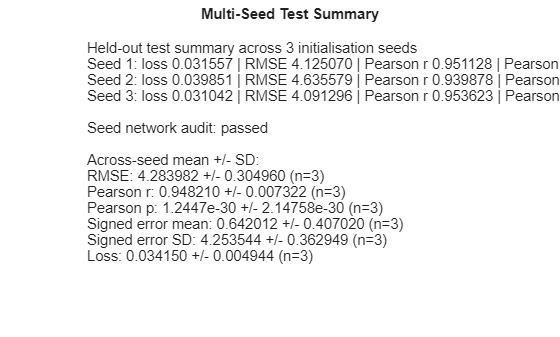

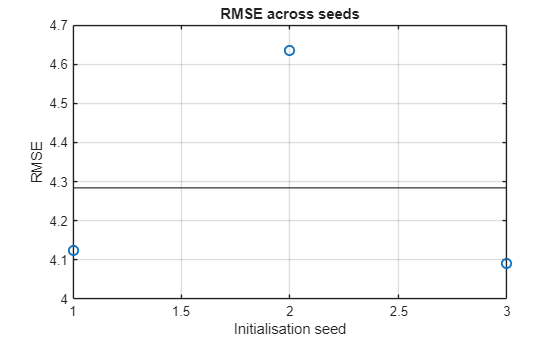

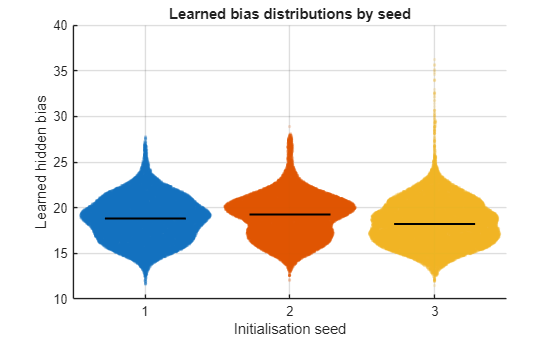

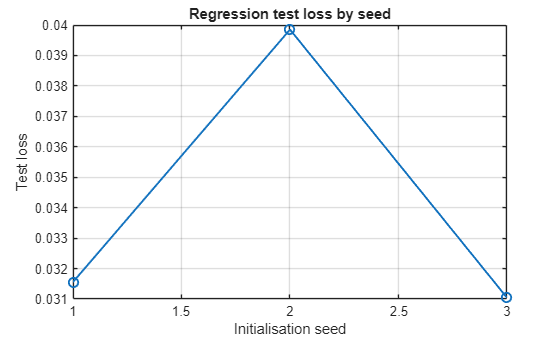

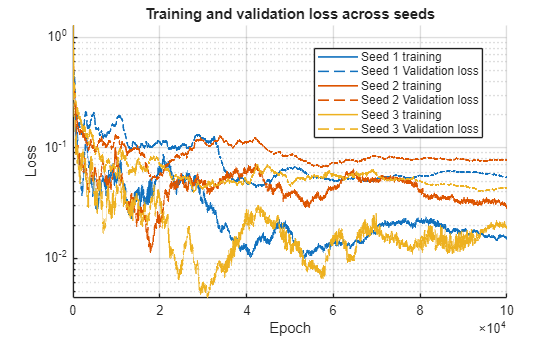

snn_plot_test_result(result);


=== Spiking Diagnostics: yacht_test_regression ===
Samples: 63 | Neurons: 32000 | Steps/sample: 300 | Seconds/sample: 0.3
Mean neuron firing rate: 2.09642 Hz | median 1.11111 Hz | 95th percentile 7.24868 Hz
Active neurons: 25275 / 32000 (78.98%)
Silent neurons: 6725 / 32000 (21.02%)
Mean population rate by sample: 2.09642 Hz/neuron
Mean active neurons by sample: 32.19% | silent 67.81%
Total within-sample ISIs counted: 619062
Median per-neuron mean inverse-ISI rate: 9.16192 Hz


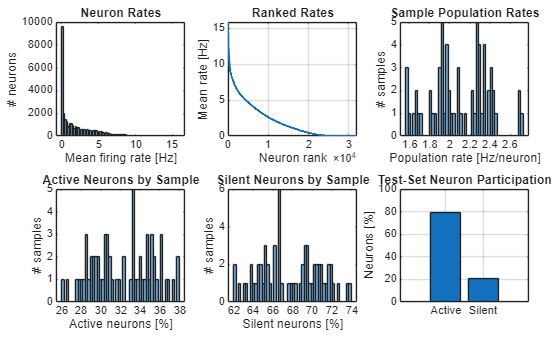

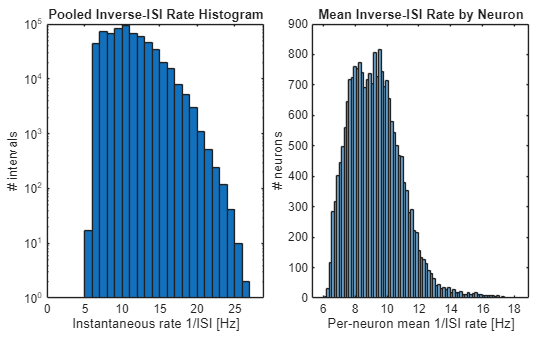

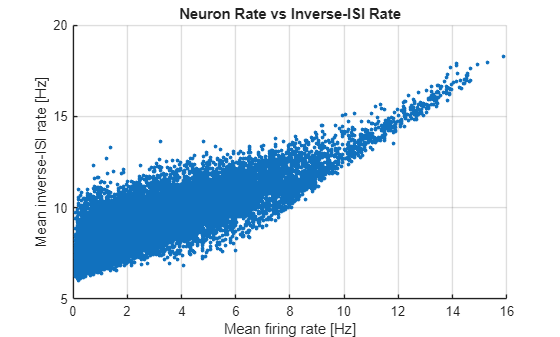

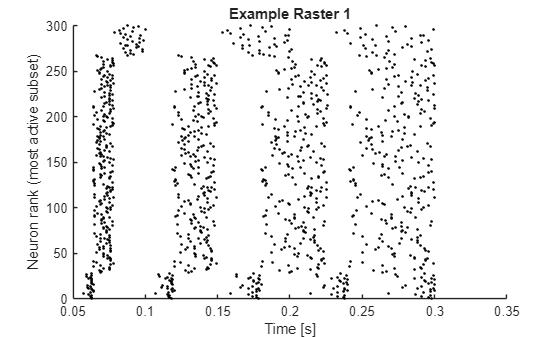

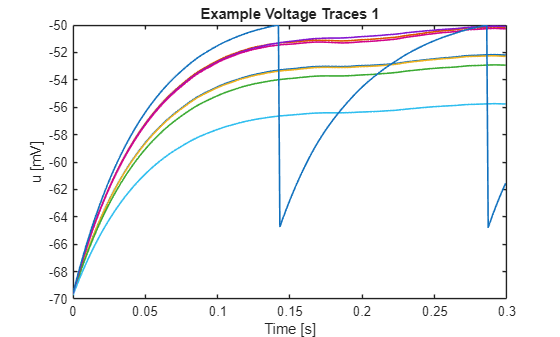

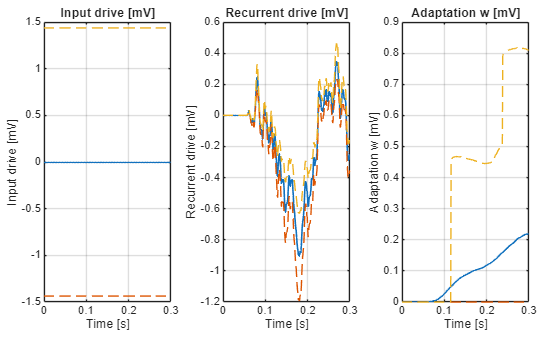

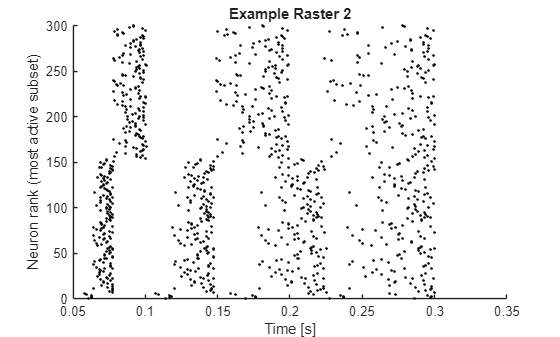

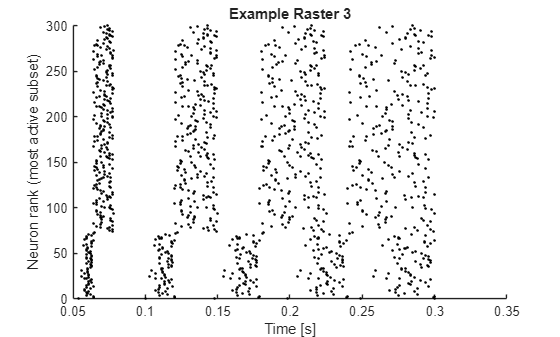

[SPIKING] Displayed spiking diagnostics without saving files. To save files, pass 'save_files', true.



%% ---------------- Spiking Dynamics Diagnostics ----------------
% These diagnostics replay the saved trained network through the CPU reference
% to produce spike rasters, firing-rate summaries, ISI histograms, voltage traces,
% input/recurrent/adaptation current summaries. By default they display inline only.
diag_opts = struct();
diag_opts.model_file = model_file;
diag_opts.output_dir = diag_dir;
diag_opts.save_files = save_diagnostic_files;
diag_opts.max_samples = 8e60;
diag = snn_primary_api('spike_diagnostics_static', 'regression', 'cpu', diag_opts);

fprintf('Test spiking active neurons: %.2f%%%% (%d/%d); silent neurons: %.2f%%%% (%d/%d).\n', ...
    diag.active_neuron_percent, diag.active_neuron_count, diag.n_neurons, ...
    diag.silent_neuron_percent, diag.silent_neuron_count, diag.n_neurons);

Test spiking active neurons: 78.98%% (25275/32000); silent neurons: 21.02%% (6725/32000).


fprintf('Mean per-sample active neurons: %.2f%%%%; silent neurons: %.2f%%%%.\n', ...
    mean(diag.active_percent_by_sample), mean(diag.silent_percent_by_sample));

Mean per-sample active neurons: 32.19%%; silent neurons: 67.81%%.


fprintf('Loaded trained network from:\n%s\n', model_file);

Loaded trained network from:
C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\models\regression_yacht_gpu_primary_seed001.mat


fprintf('Displayed test plots and spiking diagnostics inline. Set save_diagnostic_files=true to write diagnostics to disk.\n');

Displayed test plots and spiking diagnostics inline. Set save_diagnostic_files=true to write diagnostics to disk.


disp(result.test);

          loss: 0.0316
        metric: 0.9511
         count: 63
             Z: [-0.5634 -0.5129 -0.4967 -0.6586 -0.4436 -0.6397 -0.8388 -0.7252 -0.6137 1.6068 -0.4704 1.3641 0.9783 -0.0247 -0.4208 1.0882 -0.6509 0.3654 -0.5110 -0.6871 -0.5461 -0.5224 1.3946 -0.8461 -0.8338 -0.6341 -0.6431 -0.6634 … ] (1×63 single)
             Y: [-0.6447 -0.4260 -0.7007 -0.4638 -0.6465 -0.6075 -0.6782 -0.6526 -0.7135 1.2146 -0.5479 1.2743 0.6836 -0.2823 -0.7105 0.5228 -0.7056 -0.0162 -0.4912 -0.5606 -0.6678 -0.7050 1.8237 -0.6916 -0.6246 -0.7196 -0.6410 -0.5686 … ] (1×63 single)
    regression: [1×1 struct]

